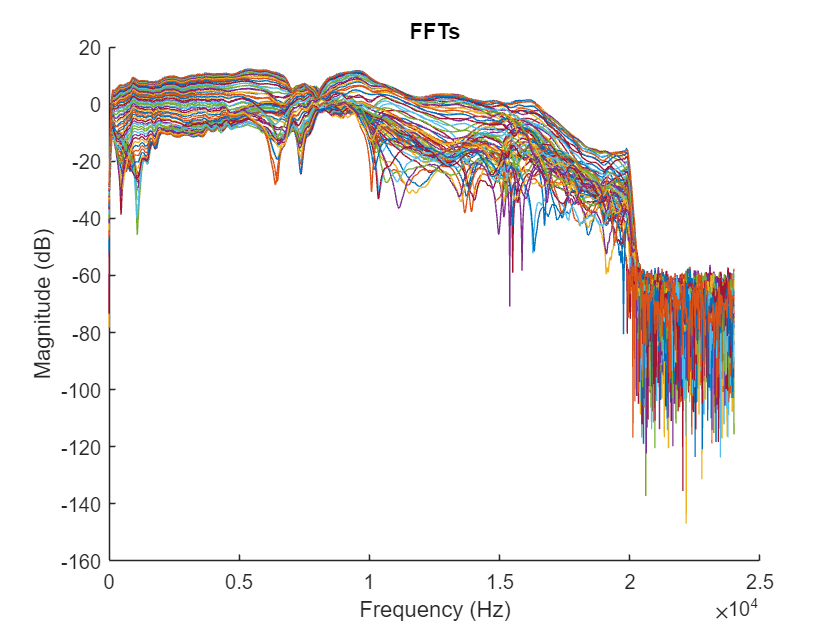

angles = 0:5:355;
num_angles = length(angles);
ir_data = cell(1, num_angles);
fft_data = cell(1, num_angles);

polar_freq = [500 1000 2000 4000];
num_polar_freq = length(polar_freq);
polars = zeros(num_polar_freq, num_angles);

figure;
hold on;
for i = 1:num_angles
    filename = sprintf("Microphone_Impulse_Responses\\ShureSM58_125cm_Normalised_IRs\\IRs\\ShureSM58_125cm_%dDeg.wav", angles(i));
    [ir_data{i}, fs] = audioread(filename);
    N = length(ir_data{i});
    freq = (1:N)*(fs/N);
    freq = freq(1:N/2);
    fft_data{i} = fft(ir_data{i});
    magnitude = 20*log10(abs(fft_data{1, i}(1:N/2)));
    for j = 1:num_polar_freq
        polars(j, i) = magnitude(polar_freq(j)*N/fs);
    end
    plot(freq, magnitude);
end
hold off;
xlabel("Frequency (Hz)");
ylabel("Magnitude (dB)");

title('FFTs');

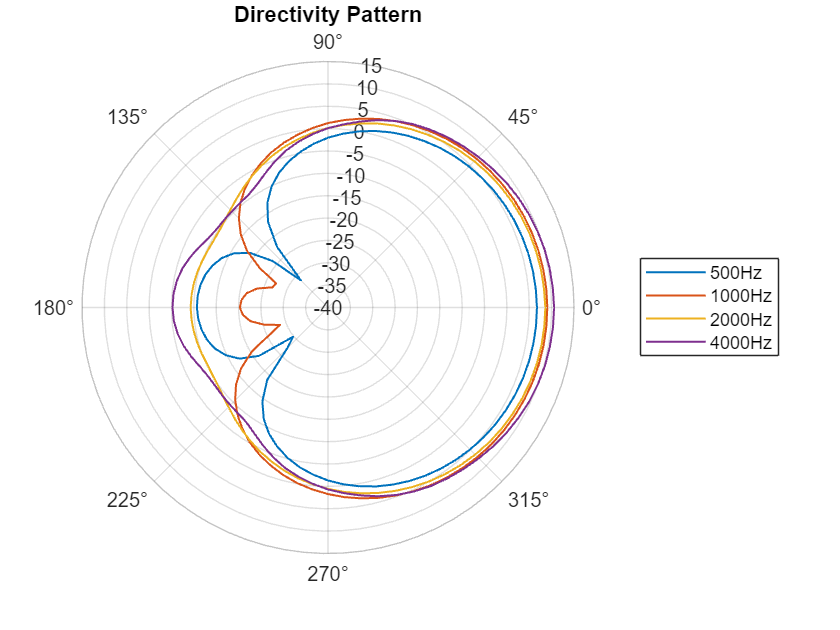

figure;
angles = [angles 360];
polars = [polars polars(:,1)];
tbl = array2table([deg2rad(angles') polars']);
tbl = renamevars(tbl, "Var1", "Angles (rad)");
polar_freq_labels = string(polar_freq);
for i = 1:num_polar_freq
    polar_freq_labels(i) = sprintf("%dHz",polar_freq(i));
    tbl = renamevars(tbl, sprintf("Var%d",i+1), sprintf("%dHz",polar_freq(i)));
end

polarplot(tbl, "Angles (rad)", polar_freq_labels, 'Linewidth', 1);
legend;
thetalim([0 360]);
thetaticks(0:45:315);
rlim([-40 15]);
rticks(-40:5:15);
title("Directivity Pattern");